% IOE 511/MATH 562, University of Michigan
% Code written by: Minghao Chen

% Script to run code
% close all figures, clear all variables from workspace and clear command
% window
% close all
clear;clc;clf
format long
 

tic
rng(0);
% set problem (minimal requirement: name of problem)
problem.name = "Rosenbrock";
problem.x0 = [-1.2;1];
problem.n = length(problem.x0);
problem.memory = 5;


% set method (minimal requirement: name of method)
method.name = 'TRSR1CG'; % option: GradientDescent, Newton, BFGS, L-BFGS
method.options.step_type = 'Backtracking'; % option: Constant, Backtracking, Modified Backtracking (Newton)
%method.options.constant_step_size = 1e-3;

% set options   
options.term_tol = 0.000001;
options.max_iterations = 1000;
% fstar = 1;

fig_name = strcat(problem.name,'_',method.name,'_',method.options.step_type,'.png');
result_name = strcat(problem.name,'_',method.name,'_',method.options.step_type,'.mat');

% h= waitbar(0,'Please wait...');
% run method and return x^* and f^*
[x,f,k,delta,norm_g] = optSolver(problem,method,options);

% output
timeElapsed = toc; 
fprintf('%15s %15s %15s %15s','Iteration','Func val','Norm Grad','CPU Seconds');

      Iteration        Func val       Norm Grad     CPU Seconds

fprintf('%15d %15.4e %15.4e %15.4f',k,f,norm_g,timeElapsed); 

             51      7.7613e-08      2.0174e-04          6.7735

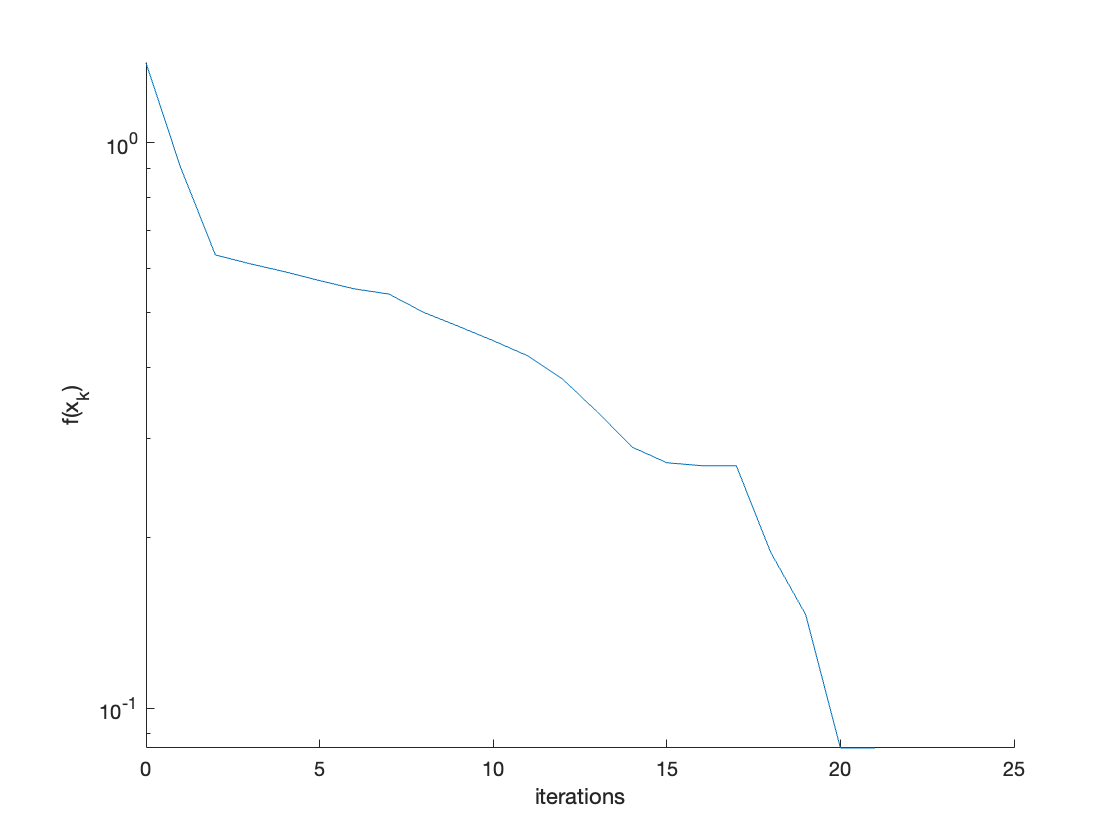


result = {'f','k','norm_g','timeElapsed';f,k,norm_g,timeElapsed};
save(result_name,"result");

% plot the difference between fx and fx v.s. iterations^*
figure(1)
plot(0:k,log10(delta(1:k+1)));
%title("Function Value");
xlabel("iterations");
ylabel("f(x_k)");
box off
hold off
set(gca,'Yscale','log') % log scale
exportgraphics(gcf,fig_name,'Resolution',500);